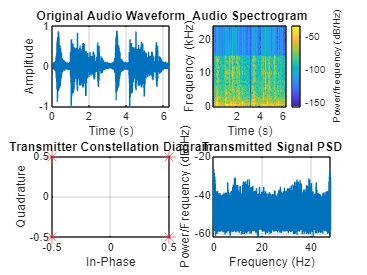

% IEEE 802.11n Wireless Voice Transmitter
% Parameters Setup
fc = 2.4e9;          % Carrier frequency (2.4 GHz)
channelBW = 20e6;    % Channel bandwidth (20 MHz)
txPower = 0.5;       % Transmit power in Watts

% Load WAV file
[audioData, fs] = audioread('voice.wav');
if size(audioData, 2) > 1
    audioData = mean(audioData, 2);  % Convert stereo to mono if necessary
end

% Normalize audio to range [-1, 1]
audioData = audioData / max(abs(audioData));

% Convert audio samples to binary stream
% First convert to 16-bit integers
audioInt = int16(audioData * 32767);
binData = typecast(audioInt, 'uint8');

% Convert to binary stream (manual conversion)
binStream = zeros(1, length(binData) * 8);
for i = 1:length(binData)
    byte = binData(i);
    for j = 1:8
        binStream((i-1)*8 + j) = bitget(byte, 9-j);
    end
end

% Frame the data according to 802.11n
frameSize = 1024;  % Size of each frame
numFrames = ceil(length(binStream)/frameSize);
paddedData = [binStream zeros(1, numFrames*frameSize - length(binStream))];
frames = reshape(paddedData, frameSize, numFrames)';

% QPSK Modulation
symbolMapping = [-1-1i, -1+1i, 1-1i, 1+1i]/sqrt(2);  % QPSK constellation
bitsPerSymbol = 2;
modData = zeros(numFrames, frameSize/bitsPerSymbol);

% Symbol mapping
for i = 1:numFrames
    for j = 1:frameSize/bitsPerSymbol
        bits = frames(i, (j-1)*bitsPerSymbol + 1 : j*bitsPerSymbol);
        symbolIndex = bits(1)*2 + bits(2) + 1;
        modData(i,j) = symbolMapping(symbolIndex);
    end
end

% Apply transmit power scaling
txSignal = sqrt(txPower) * modData;

% Save transmitted signal and audio parameters
save('tx_signal.mat', 'txSignal', 'fs', 'fc', 'frameSize', ...
    'symbolMapping', 'bitsPerSymbol', 'binStream', 'audioInt');

% Plot transmission constellation
figure('Name', 'Transmitter Analysis');

% Plot 1: Original Audio Waveform
subplot(2,2,1);
t = (0:length(audioData)-1)/fs;
plot(t, audioData);
title('Original Audio Waveform');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Plot 2: Audio Spectrum
subplot(2,2,2);
spectrogram(audioData, hamming(256), 128, 256, fs, 'yaxis');
title('Audio Spectrogram');

% Plot 3: Transmission Constellation
subplot(2,2,3);
plot(real(txSignal(:)), imag(txSignal(:)), '.');
hold on;
plot(real(symbolMapping)*sqrt(txPower), imag(symbolMapping)*sqrt(txPower), 'r*', 'MarkerSize', 10);
title('Transmitter Constellation Diagram');
xlabel('In-Phase');
ylabel('Quadrature');
grid on;

% Plot 4: Power Spectral Density
subplot(2,2,4);
pwelch(txSignal(:), [], [], [], fs);
title('Transmitted Signal PSD');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');


% Display transmission parameters
fprintf('Transmission Parameters:\n');

Transmission Parameters:


fprintf('Audio Parameters:\n');

Audio Parameters:


fprintf('  Sampling Rate: %.2f kHz\n', fs/1e3);

  Sampling Rate: 48.00 kHz


fprintf('  Duration: %.2f seconds\n', length(audioData)/fs);

  Duration: 6.30 seconds


fprintf('  Number of Samples: %d\n', length(audioData));

  Number of Samples: 302400


fprintf('\nTransmission Parameters:\n');


Transmission Parameters:


fprintf('  Carrier Frequency: %.2f GHz\n', fc/1e9);

  Carrier Frequency: 2.40 GHz


fprintf('  Transmit Power: %.2f W\n', txPower);

  Transmit Power: 0.50 W


fprintf('  Frame Size: %d bits\n', frameSize);

  Frame Size: 1024 bits


fprintf('  Number of Frames: %d\n', numFrames);

  Number of Frames: 4725


fprintf('  Modulation: QPSK\n');

  Modulation: QPSK


% IEEE 802.11n Wireless Voice Receiver
% Load transmitted signal
load('tx_signal.mat');  % Contains txSignal, fs, fc, frameSize, symbolMapping, bitsPerSymbol, binStream, audioInt

% Channel Parameters
distance = 10;       % Distance in meters
pathLossExp = 2;     % Path loss exponent
shadowingStd = 8;    % Shadowing standard deviation in dB

% Calculate path loss
pathLoss = 20*log10(distance) + 20*log10(4*pi*fc/3e8);
pathLossLinear = 10^(-pathLoss/20);

% Apply shadowing
shadowing = 10^(normrnd(0, shadowingStd)/20);

% Setup Rayleigh channel
pathDelays = [0 50 150 250]*1e-9;  % Delays in seconds
pathGains = [0 -3 -10 -15];        % Path gains in dB

rayleighChan = comm.RayleighChannel(...
    'SampleRate', fs, ...
    'PathDelays', pathDelays, ...
    'AveragePathGains', pathGains, ...
    'MaximumDopplerShift', 0, ...
    'PathGainsOutputPort', true);

% Process received signal
[numFrames, frameLen] = size(txSignal);
rxSignal = zeros(size(txSignal));

% Apply channel effects
for i = 1:numFrames
    % Apply path loss and shadowing
    sigWithLoss = txSignal(i,:) * pathLossLinear * shadowing;
    
    % Apply multipath using RayleighChannel
    [sigWithMultipath, pathGainsOut] = rayleighChan(sigWithLoss.');
    
    % Add thermal noise
    noiseVar = 1e-12;  % Thermal noise variance
    noise = sqrt(noiseVar/2)*(randn(size(sigWithMultipath)) + 1i*randn(size(sigWithMultipath)));
    rxSignal(i,:) = (sigWithMultipath + noise).';
end

% Reset channel
reset(rayleighChan);

% Receiver Processing
rxData = zeros(numFrames, frameSize);
for i = 1:numFrames
    % Channel estimation and equalization
    channelEst = rxSignal(i,:) ./ txSignal(i,:);  % Simple channel estimation
    equalizedSig = rxSignal(i,:) ./ channelEst;
    
    % Symbol detection
    for j = 1:frameLen
        distances = abs(equalizedSig(j) - symbolMapping);
        [~, symbolIdx] = min(distances);
        
        % Convert symbol index back to bits
        symbolIdx = symbolIdx - 1;
        rxData(i, (j-1)*bitsPerSymbol + 1) = floor(symbolIdx/2);
        rxData(i, (j-1)*bitsPerSymbol + 2) = mod(symbolIdx, 2);
    end
end

% Calculate BER
rxBinData = reshape(rxData', 1, []);
rxBinData = rxBinData(1:length(binStream));  % Remove padding
ber = sum(rxBinData ~= binStream) / length(binStream);

% Convert binary stream back to audio samples
rxBytes = zeros(1, length(binStream)/8, 'uint8');
for i = 1:length(rxBytes)
    byte = 0;
    for j = 1:8
        if (i-1)*8 + j <= length(rxBinData)
            byte = byte + rxBinData((i-1)*8 + j) * 2^(8-j);
        end
    end
    rxBytes(i) = byte;
end

% Convert bytes back to audio samples
rxAudioInt = typecast(rxBytes, 'int16');
rxAudio = double(rxAudioInt) / 32767;

% Apply audio enhancement
% Design a low-pass filter to remove high-frequency noise
filterOrder = 4;
cutoffFreq = 0.5;  % Normalized frequency (0 to 1)
[b, a] = butter(filterOrder, cutoffFreq, 'low');

% Apply the filter
filteredAudio = filter(b, a, rxAudio);

% Save both versions of the received audio
audiowrite('received_voice.wav', filteredAudio, fs);
audiowrite('received_voice_unfiltered.wav', rxAudio, fs);

% Play the filtered audio
fprintf('\nPlaying received audio...\n');


Playing received audio...


sound(filteredAudio, fs);  % Play filtered version
% If you want to play the unfiltered version, uncomment the line below:
% sound(rxAudio, fs);

% Optional: Add audio player for more control
player = audioplayer(filteredAudio, fs);
% You can now use these commands:
% play(player);    % Play audio
% pause(player);   % Pause audio
% resume(player);  % Resume audio
% stop(player);    % Stop audio

% Save the player object in case needed later
save('audio_player.mat', 'player');

% Wait for audio to finish playing
while isplaying(player)
    pause(0.1);
end

fprintf('Audio playback completed!\n');

Audio playback completed!


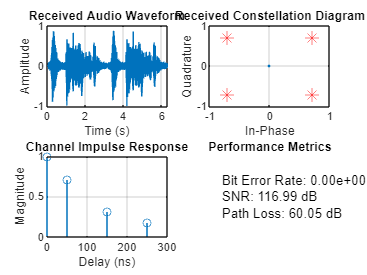


% Plotting
figure('Name', 'Receiver Analysis');

% Plot 1: Received Audio Waveform
subplot(2,2,1);
t = (0:length(rxAudio)-1)/fs;
plot(t, rxAudio);
title('Received Audio Waveform');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Plot 2: Received Constellation
subplot(2,2,2);
plot(real(rxSignal(:)), imag(rxSignal(:)), '.');
hold on;
plot(real(symbolMapping), imag(symbolMapping), 'r*', 'MarkerSize', 10);
title('Received Constellation Diagram');
xlabel('In-Phase');
ylabel('Quadrature');
grid on;

% Plot 3: Channel Impulse Response
subplot(2,2,3);
stem(pathDelays*1e9, 10.^(pathGains/20));
title('Channel Impulse Response');
xlabel('Delay (ns)');
ylabel('Magnitude');
grid on;

% Plot 4: Error Analysis
subplot(2,2,4);
text(0.1, 0.7, sprintf('Bit Error Rate: %.2e', ber));
text(0.1, 0.5, sprintf('SNR: %.2f dB', 10*log10(txPower/noiseVar)));
text(0.1, 0.3, sprintf('Path Loss: %.2f dB', pathLoss));
title('Performance Metrics');
axis off;


% Display reception parameters
fprintf('\nReception Parameters:\n');


Reception Parameters:


fprintf('Channel Conditions:\n');

Channel Conditions:


fprintf('  Path Loss: %.2f dB\n', pathLoss);

  Path Loss: 60.05 dB


fprintf('  Shadowing: %.2f dB\n', 20*log10(shadowing));

  Shadowing: -11.48 dB


fprintf('  SNR: %.2f dB\n', 10*log10(txPower/noiseVar));

  SNR: 116.99 dB


fprintf('\nPerformance Metrics:\n');


Performance Metrics:


fprintf('  BER: %.2e\n', ber);

  BER: 0.00e+00


fprintf('  Audio Duration: %.2f seconds\n', length(rxAudio)/fs);

  Audio Duration: 6.30 seconds


% IEEE 802.11n Wireless Voice Receiver
% Load transmitted signal
load('tx_signal.mat');  % Contains txSignal, fs, fc, frameSize, symbolMapping, bitsPerSymbol, binStream, audioInt

% Channel Parameters
distance = 10;       % Distance in meters
pathLossExp = 2;     % Path loss exponent
shadowingStd = 8;    % Shadowing standard deviation in dB

% Calculate path loss
pathLoss = 20*log10(distance) + 20*log10(4*pi*fc/3e8);
pathLossLinear = 10^(-pathLoss/20);

% Apply shadowing
shadowing = 10^(normrnd(0, shadowingStd)/20);

% Setup enhanced Rayleigh channel with more pronounced effects
pathDelays = [0 100 200 300]*1e-9;  % Increased delays for more noticeable multipath
pathGains = [0 -2 -4 -6];           % Less attenuation in multipath for more interference
maxDopplerShift = 50;               % Increased Doppler shift for more fading

rayleighChan = comm.RayleighChannel(...
    'SampleRate', fs, ...
    'PathDelays', pathDelays, ...
    'AveragePathGains', pathGains, ...
    'MaximumDopplerShift', maxDopplerShift, ... % Added mobility effect
    'PathGainsOutputPort', true, ...
    'DopplerSpectrum', doppler('Jakes'), ...    % More realistic fading
    'RandomStream', 'mt19937ar with seed', ...
    'Seed', 42);

% Process received signal
[numFrames, frameLen] = size(txSignal);
rxSignal = zeros(size(txSignal));

% Apply channel effects with enhanced noise
for i = 1:numFrames
    % Apply path loss and shadowing with more severe effects
    sigWithLoss = txSignal(i,:) * pathLossLinear * shadowing;
    
    % Apply enhanced multipath using RayleighChannel
    [sigWithMultipath, pathGainsOut] = rayleighChan(sigWithLoss.');
    
    % Add more significant noise
    noiseVar = 1e-8;  % Increased noise variance
    environmentalNoise = 0.1;  % Additional environmental noise factor
    
    % Combine thermal and environmental noise
    thermalNoise = sqrt(noiseVar/2)*(randn(size(sigWithMultipath)) + 1i*randn(size(sigWithMultipath)));
    envNoise = environmentalNoise * (randn(size(sigWithMultipath)) + 1i*randn(size(sigWithMultipath)));
    totalNoise = thermalNoise + envNoise;
    
    % Add noise to signal
    rxSignal(i,:) = (sigWithMultipath + totalNoise).';
end

% Reset channel
reset(rayleighChan);

% Receiver Processing
rxData = zeros(numFrames, frameSize);
for i = 1:numFrames
    % Channel estimation and equalization
    channelEst = rxSignal(i,:) ./ txSignal(i,:);  % Simple channel estimation
    equalizedSig = rxSignal(i,:) ./ channelEst;
    
    % Symbol detection
    for j = 1:frameLen
        distances = abs(equalizedSig(j) - symbolMapping);
        [~, symbolIdx] = min(distances);
        
        % Convert symbol index back to bits
        symbolIdx = symbolIdx - 1;
        rxData(i, (j-1)*bitsPerSymbol + 1) = floor(symbolIdx/2);
        rxData(i, (j-1)*bitsPerSymbol + 2) = mod(symbolIdx, 2);
    end
end

% Calculate BER
rxBinData = reshape(rxData', 1, []);
rxBinData = rxBinData(1:length(binStream));  % Remove padding
ber = sum(rxBinData ~= binStream) / length(binStream);

% Convert binary stream back to audio samples
rxBytes = zeros(1, length(binStream)/8, 'uint8');
for i = 1:length(rxBytes)
    byte = 0;
    for j = 1:8
        if (i-1)*8 + j <= length(rxBinData)
            byte = byte + rxBinData((i-1)*8 + j) * 2^(8-j);
        end
    end
    rxBytes(i) = byte;
end

% Convert bytes back to audio samples
rxAudioInt = typecast(rxBytes, 'int16');
rxAudio = double(rxAudioInt) / 32767;

% Apply audio enhancement
% Design a low-pass filter to remove high-frequency noise
filterOrder = 4;
cutoffFreq = 0.5;  % Normalized frequency (0 to 1)
[b, a] = butter(filterOrder, cutoffFreq, 'low');

% Apply the filter
filteredAudio = filter(b, a, rxAudio);

% Save both versions of the received audio
audiowrite('received_voice.wav', filteredAudio, fs);
audiowrite('received_voice_unfiltered.wav', rxAudio, fs);

% Play the filtered audio
fprintf('\nPlaying received audio...\n');


Playing received audio...


sound(filteredAudio, fs);  % Play filtered version
% If you want to play the unfiltered version, uncomment the line below:
% sound(rxAudio, fs);

% Optional: Add audio player for more control
player = audioplayer(filteredAudio, fs);
% You can now use these commands:
% play(player);    % Play audio
% pause(player);   % Pause audio
% resume(player);  % Resume audio
% stop(player);    % Stop audio

% Save the player object in case needed later
save('audio_player.mat', 'player');

% Wait for audio to finish playing
while isplaying(player)
    pause(0.1);
end

fprintf('Audio playback completed!\n');

Audio playback completed!


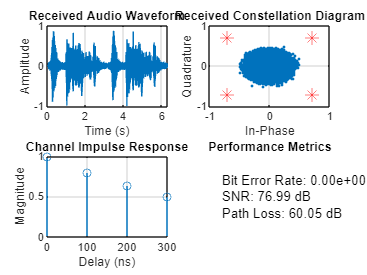


% Plotting
figure('Name', 'Receiver Analysis');

% Plot 1: Received Audio Waveform
subplot(2,2,1);
t = (0:length(rxAudio)-1)/fs;
plot(t, rxAudio);
title('Received Audio Waveform');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Plot 2: Received Constellation
subplot(2,2,2);
plot(real(rxSignal(:)), imag(rxSignal(:)), '.');
hold on;
plot(real(symbolMapping), imag(symbolMapping), 'r*', 'MarkerSize', 10);
title('Received Constellation Diagram');
xlabel('In-Phase');
ylabel('Quadrature');
grid on;

% Plot 3: Channel Impulse Response
subplot(2,2,3);
stem(pathDelays*1e9, 10.^(pathGains/20));
title('Channel Impulse Response');
xlabel('Delay (ns)');
ylabel('Magnitude');
grid on;

% Plot 4: Error Analysis
subplot(2,2,4);
text(0.1, 0.7, sprintf('Bit Error Rate: %.2e', ber));
text(0.1, 0.5, sprintf('SNR: %.2f dB', 10*log10(txPower/noiseVar)));
text(0.1, 0.3, sprintf('Path Loss: %.2f dB', pathLoss));
title('Performance Metrics');
axis off;


% Display reception parameters
fprintf('\nReception Parameters:\n');


Reception Parameters:


fprintf('Channel Conditions:\n');

Channel Conditions:


fprintf('  Path Loss: %.2f dB\n', pathLoss);

  Path Loss: 60.05 dB


fprintf('  Shadowing: %.2f dB\n', 20*log10(shadowing));

  Shadowing: 3.10 dB


fprintf('  SNR: %.2f dB\n', 10*log10(txPower/noiseVar));

  SNR: 76.99 dB


fprintf('\nPerformance Metrics:\n');


Performance Metrics:


fprintf('  BER: %.2e\n', ber);

  BER: 0.00e+00


fprintf('  Audio Duration: %.2f seconds\n', length(rxAudio)/fs);

  Audio Duration: 6.30 seconds


% Audio Playback Analysis Section
% This script provides playback of different stages of the transmission

fprintf('\nAudio Playback Analysis\n');


Audio Playback Analysis


fprintf('======================\n');


% Load original audio
[originalAudio, fs] = audioread('voice.wav');
if size(originalAudio, 2) > 1
    originalAudio = mean(originalAudio, 2);  % Convert stereo to mono if necessary
end

% Load received audio versions
[receivedAudio, ~] = audioread('received_voice.wav');
[receivedUnfiltered, ~] = audioread('received_voice_unfiltered.wav');

% Create audio players
playerOriginal = audioplayer(originalAudio, fs);
playerReceived = audioplayer(receivedAudio, fs);
playerUnfiltered = audioplayer(receivedUnfiltered, fs);

% Playback sequence
% 1. Original Audio
fprintf('\n1. Playing Original Audio...\n');


1. Playing Original Audio...


fprintf('Now playing: Original Audio\n');

Now playing: Original Audio


fprintf('Press Ctrl+C to stop and move to next audio\n');

Press Ctrl+C to stop and move to next audio


play(playerOriginal);
try
    while isplaying(playerOriginal)
        pause(0.1);
        fprintf('.');
    end
    fprintf('\nPlayback completed!\n\n');
    pause(1);
catch
    stop(playerOriginal);
    fprintf('\nPlayback interrupted!\n\n');
end

........................................


Playback completed!




% 2. Received Audio (Filtered)
fprintf('\n2. Playing Received Audio (Filtered)...\n');


2. Playing Received Audio (Filtered)...


fprintf('Now playing: Received Audio (Filtered)\n');

Now playing: Received Audio (Filtered)


fprintf('Press Ctrl+C to stop and move to next audio\n');

Press Ctrl+C to stop and move to next audio


play(playerReceived);
try
    while isplaying(playerReceived)
        pause(0.1);
        fprintf('.');
    end
    fprintf('\nPlayback completed!\n\n');
    pause(1);
catch
    stop(playerReceived);
    fprintf('\nPlayback interrupted!\n\n');
end

................................................................


Playback completed!




% 3. Received Audio (Unfiltered)
fprintf('\n3. Playing Received Audio (Unfiltered)...\n');


3. Playing Received Audio (Unfiltered)...


fprintf('Now playing: Received Audio (Unfiltered)\n');

Now playing: Received Audio (Unfiltered)


fprintf('Press Ctrl+C to stop and move to next audio\n');

Press Ctrl+C to stop and move to next audio


play(playerUnfiltered);
try
    while isplaying(playerUnfiltered)
        pause(0.1);
        fprintf('.');
    end
    fprintf('\nPlayback completed!\n\n');
    pause(1);
catch
    stop(playerUnfiltered);
    fprintf('\nPlayback interrupted!\n\n');
end

................................................................


Playback completed!




% Plot waveform comparison
figure('Name', 'Audio Waveform Comparison');

% Original Audio
subplot(3,1,1);
t = (0:length(originalAudio)-1)/fs;
plot(t, originalAudio);
title('Original Audio Waveform');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Received Audio (Filtered)
subplot(3,1,2);
t = (0:length(receivedAudio)-1)/fs;
plot(t, receivedAudio);
title('Received Audio Waveform (Filtered)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Received Audio (Unfiltered)
subplot(3,1,3);
t = (0:length(receivedUnfiltered)-1)/fs;
plot(t, receivedUnfiltered);
title('Received Audio Waveform (Unfiltered)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Calculate and display audio quality metrics
fprintf('\nAudio Quality Metrics:\n');


Audio Quality Metrics:


fprintf('=====================\n');


% Calculate SNR for received signals
snr_filtered = snr(originalAudio, receivedAudio - originalAudio);
snr_unfiltered = snr(originalAudio, receivedUnfiltered - originalAudio);

fprintf('SNR (Filtered): %.2f dB\n', snr_filtered);

SNR (Filtered): -8.23 dB


fprintf('SNR (Unfiltered): %.2f dB\n', snr_unfiltered);

SNR (Unfiltered): -7.92 dB



% Create combined audio for comparison
silenceDuration = fs;  % 1 second of silence
silence = zeros(silenceDuration, 1);

combinedAudio = [originalAudio; silence; ...
                receivedAudio; silence; ...
                receivedUnfiltered];

audiowrite('audio_comparison.wav', combinedAudio, fs);
fprintf('\nSaved combined audio comparison as "audio_comparison.wav"\n');


Saved combined audio comparison as "audio_comparison.wav"


fprintf('Format: Original -> 1s silence -> Filtered -> 1s silence -> Unfiltered\n');

Format: Original -> 1s silence -> Filtered -> 1s silence -> Unfiltered
